# Neural Networks Classification

## Introduction

The file `data5.mat` contains:

- $5000$ sample of handwritten digits in the matrix $X \in \mathcal M_{5000, 400}(\mathbb R)$ ($20\times20 px$ each);

- the associated $5000$ digit value in the column-vector $Y\in \mathcal M_{5000, 1}(\mathbb R)$ (we have identified the digit $0$ with the value $10$);

- the sample $\Theta \in \{\mathcal M_{401, 25}(\mathbb R), \mathcal M_{26, 10}(\mathbb R)\}$ set of some slightly trained weights for the neural network;

- the row-vector $s \in \mathcal M_{1, 3}(\mathbb N)$ with the number of units for each Layer.

Using the forward and the error backward propagation algorithm we will extimate the gradient of the cost function.

## Data Loading and Representation

In a general case we will load the two matrices $X \in \mathcal M_{m, n}(\mathbb R)$ and $Y \in \mathcal M_{m, 1}(\mathbb R)$ of respectivelly the Values and the evaluations of the training set.

In this particular case we have that the $i$-th row is a sample of the $Y[i]$ digit and the $n$ elements of each row of $X$ are the pixels of the handwritten digit scan (represented by a $20 \times 20$ matrix).

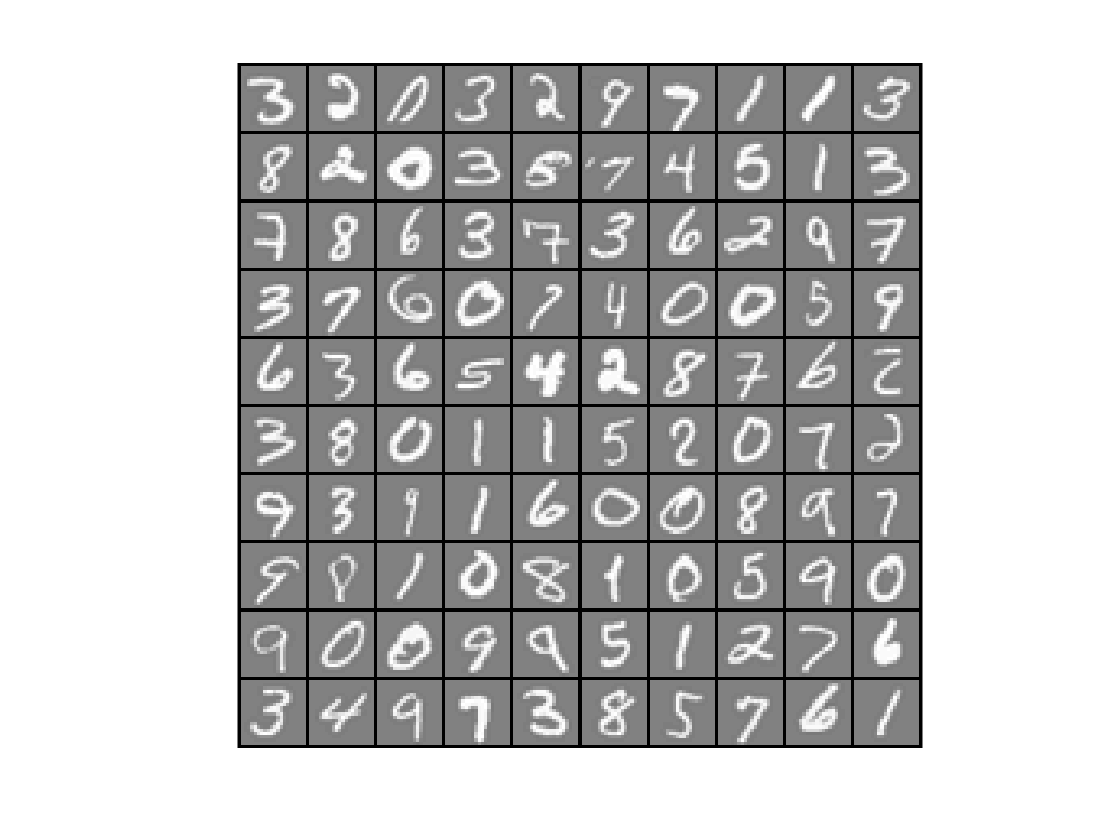

load('data5.mat', "X", "y");

[m, n] = size(X);
assert(isequal(size(y), [m, 1]));
classes = length(unique(y));

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

## Evaluation

### Neural Network Configuration

In order to build a Neural Network we have to decide a few parameters:

- the total number of Layers $L$ we will use in our neural network. Note that there will be $L - 2$ hidden layers.

- the number of units $s_l$ (without taking into account the bias) for each layer $l$.

Obs. Note that a standard choice of $L$ is 3 while a standard value for $s \in \mathcal M_{1, L}(\mathbb R)$ in any classification problem is:

    
$$s_l = \begin{cases} n & l = 1\\ k & 1 < l < L\\ \texttt{classes} & l = L \end{cases}$$


    where $k \in \mathbb N$ is some constant.

We should therefore choose randomly the values of the weights $\Theta$. Here $\Theta\{l\}(i,j) \to \Theta_{i,j}^{(l)}$ represents the weight between the $i$-th unit at layer $l$ and the $j$-th unit at layer $l+1$. In this example we have prepeared some slightly trained values in the file `data5.mat`.

load('data5.mat', "Theta", "s");
L = length(s);

### Cost Evaluation

The function `neural_cost` has a few parameter:

- $\Theta$: $L-1$ Cell-row-vector of the weight matrices between each couple of layers. $\Theta^{(l)}_{i, j}$ is the weight from $i$-th unit in the layer $l$ to the $j$-th unit in the layer $l+1$.

- s: $L$ row-vector of the number of units in each layer.

- X: $m \times n$ matrix of the Training Set Features; each row represents a sample with $n$ features.

- y: $m$ column vector of the Training Set Samples.

- $\lambda$: regularization parameter.

- `ch_bias`: Unless it is setted to $1$, the function won't change the weights associated to bias values.

And evaluate both the cost function and the associated gradient:

- $J$: Cost associated to the input weigths.

- $\nabla$: $L-1$ Cell-row-vector of the gradient value of $J$. $\nabla^{(l)}_{i, j}$ is the derivative of $J$ with respect to $\Theta^{(l)}_{i j}$.

In order to understand better how it works, we now present the computational pipeline (described also in its documentation):

- forward propagation of the training set for each training sample

                $a^{(l+1)} = g(\Theta^{(l)} \times a^{(l)}), \quad \forall l \in[1,L-1]$, where $g(x) = \frac{1}{1-e^{-x}}$ is the Sigmoid function.

- Cost Evaluation over the last Layer 

                
$$J = \sum_i^m\sum_j^{s_L} Y_{i,j} \cdot \log(a^{(L)}_{i,j}) + (1-Y_{i,j}) \cdot \log(1-a^{(L)}_{i,j})\\
\texttt{reg} = \sum_l^{L-1} \sum_i^{s_l} \sum_j^{s_l+1} {\Theta^{(l)}_{i,j}}^2\\
J = \frac{\lambda}{2m}\texttt{reg}-\frac{1}{m}J$$


- error evaluation of the last layer

                
$$\delta^{(L)} = a^{(L)} - Y$$


- error backward propagation of the error

                
$$\delta^{(l)} = a^{(l)}_{\mbox{biasless}} \cdot (1 - a^{(l)}_{\mbox{biasless}} \cdot (\delta^{(l+1)} * \Theta^{(l)}_{\mbox{biasless}}')
\quad \forall l \in [2, L-1]$$


- evaluation of the gradient

                
$$\nabla^{(l)} = \frac1m a{(l)}' * \delta{(l+1)} \quad \forall l \in [1, L-1]$$


The function could be used to create a batch gradient descent in order to optimize the weigth values in $\Theta$.

We have precomputed all the parameters but $\lambda$. We could plot the cost function assosiciated to different $\lambda$s.

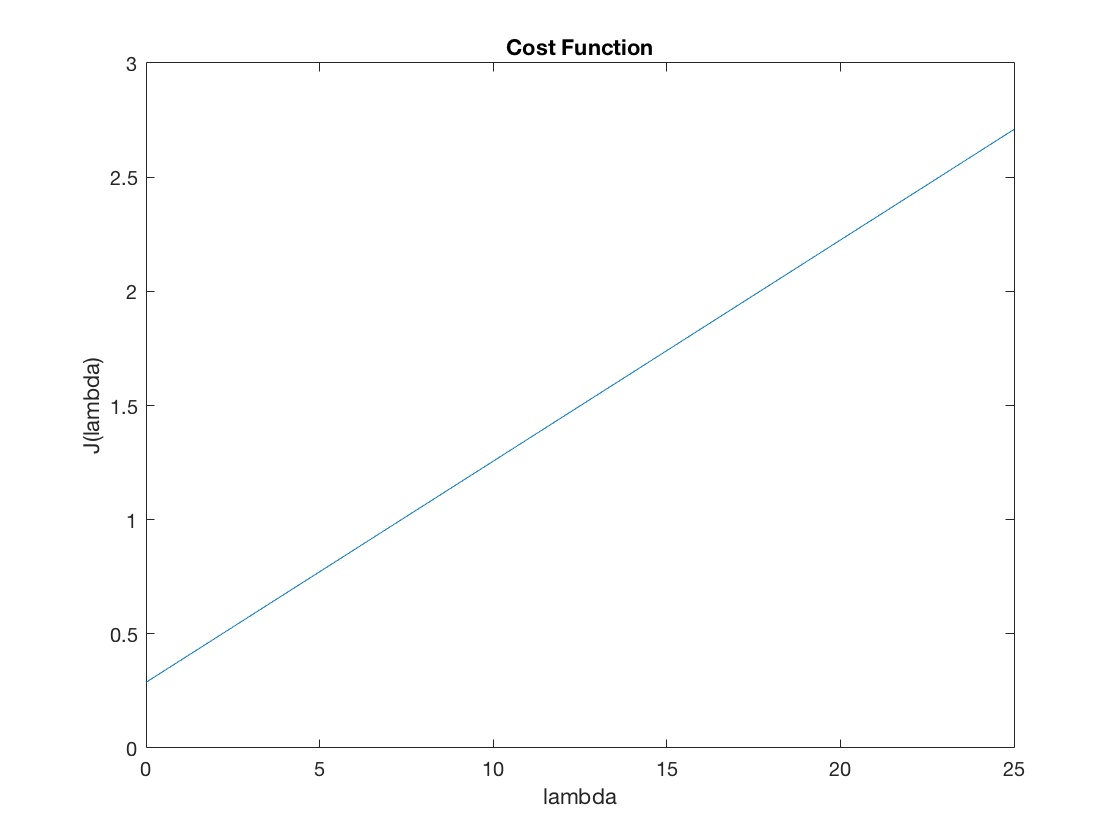

lambda = 0:25;
J  = arrayfun(@(l) neural_cost(Theta, s, X, y, l), lambda);
plot(lambda, J);
title('Cost Function');
xlabel('lambda');
ylabel('J(lambda)');

### Gradient Descent

We are finally ready to use the second output of `neural_cost` in order to optimize $\Theta$.

First of all we have to choose a parameter $\eta$ wich represent the learning rate of our algorithm. We could then use the function `neural_descent` in order to evaluate both the optimal $\Theta$ and the cost history $J_h$. It will update the $\Theta$ values according to $\Theta^{(l)}_{i, j} -= \eta\frac{\partial J}{\partial \Theta^{(l)}_{i, j}}$.

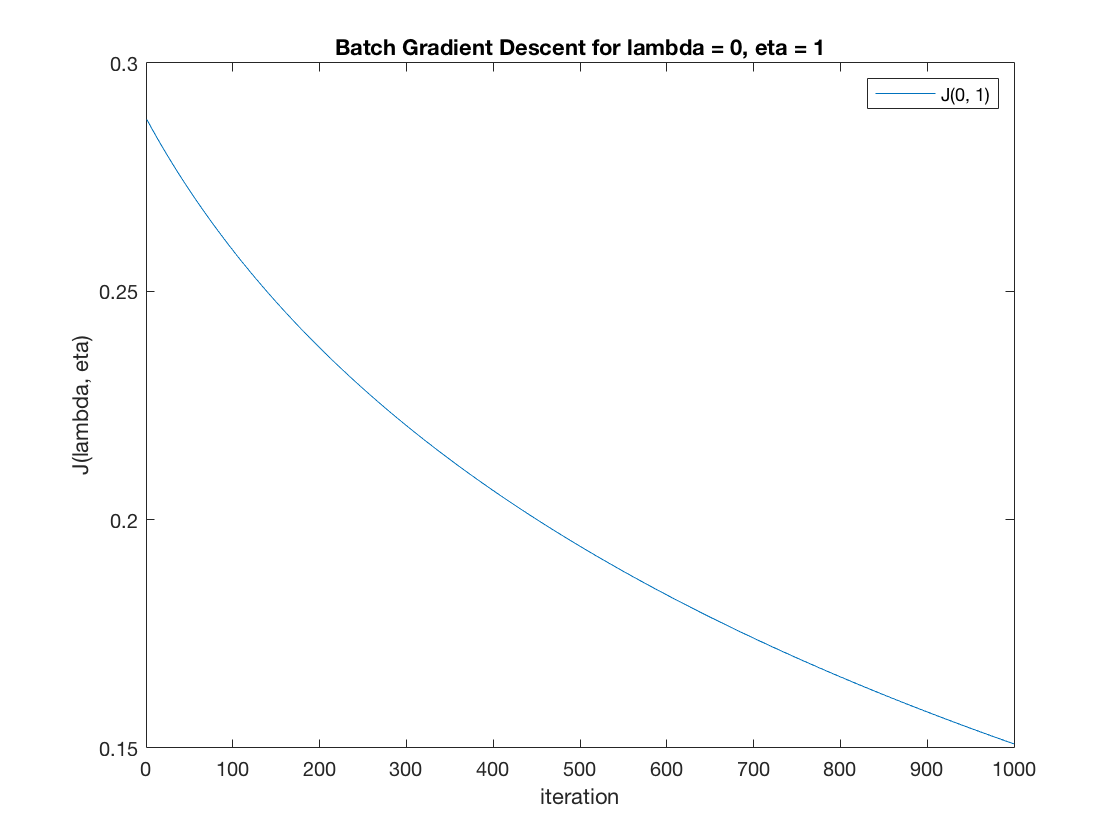

lambda = 0;
eta = 1;
[~, Jh_f, no_iter_f] = neural_descent(Theta, s, X, y, eta, lambda);
plot(1:no_iter_f, Jh_f);
title('Batch Gradient Descent for lambda = 0, eta = 1');
xlabel('iteration');
ylabel('J(lambda, eta)');
legend('J(0, 1)');

#### Gradient Descent for various $\lambda$

We could plot the results for various $\lambda$ (with fixed $\eta$) in order to obtain a clear vision of what is going on.

One interesting fact is that for $\bar\lambda=\lambda = 3$ we obtain that the cost $J$ is nearby stationary (in fact only one iteration is computed).

Therefore for each $\lambda > \bar\lambda$ the cost will be increasing.

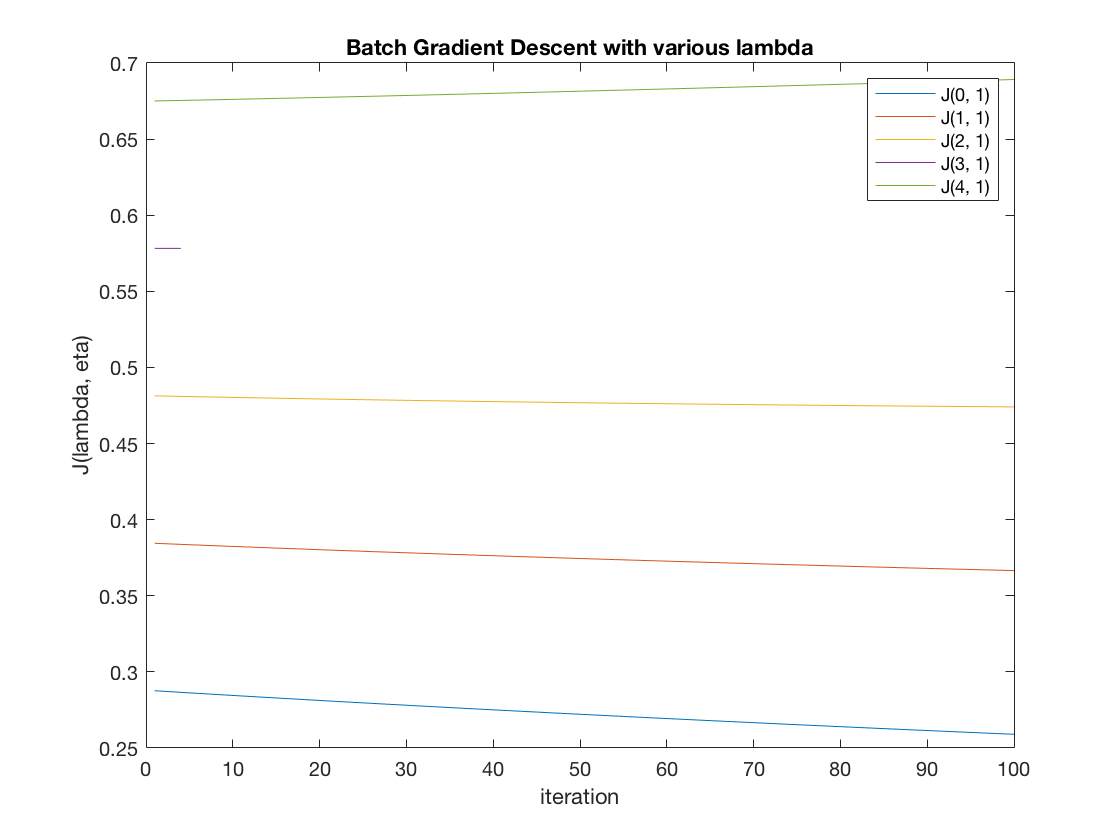

lambda = 0:4;
eta = 1;
Jh = cell(1, length(lambda));
no_iter = cell(1, length(lambda));

for l = 1 : length(lambda)
    [~, Jh{l}, no_iter{l}] = neural_descent(Theta, s, X, y, eta, lambda(l), 0.000001, 100);
end

plot(1:no_iter{1}, Jh{1});hold on
for l = 2 : length(lambda)
    plot(1:no_iter{l}, Jh{l});
end
title('Batch Gradient Descent with various lambda');
xlabel('iteration');
ylabel('J(lambda, eta)');
legend('J(0, 1)', 'J(1, 1)', 'J(2, 1)', 'J(3, 1)', 'J(4, 1)');
hold off

#### Gradient Descent for various $\eta$

We could also plot the results for various $\eta$ (with fixed $\lambda = 0$) in order to obtain a clear vision of what is going on.

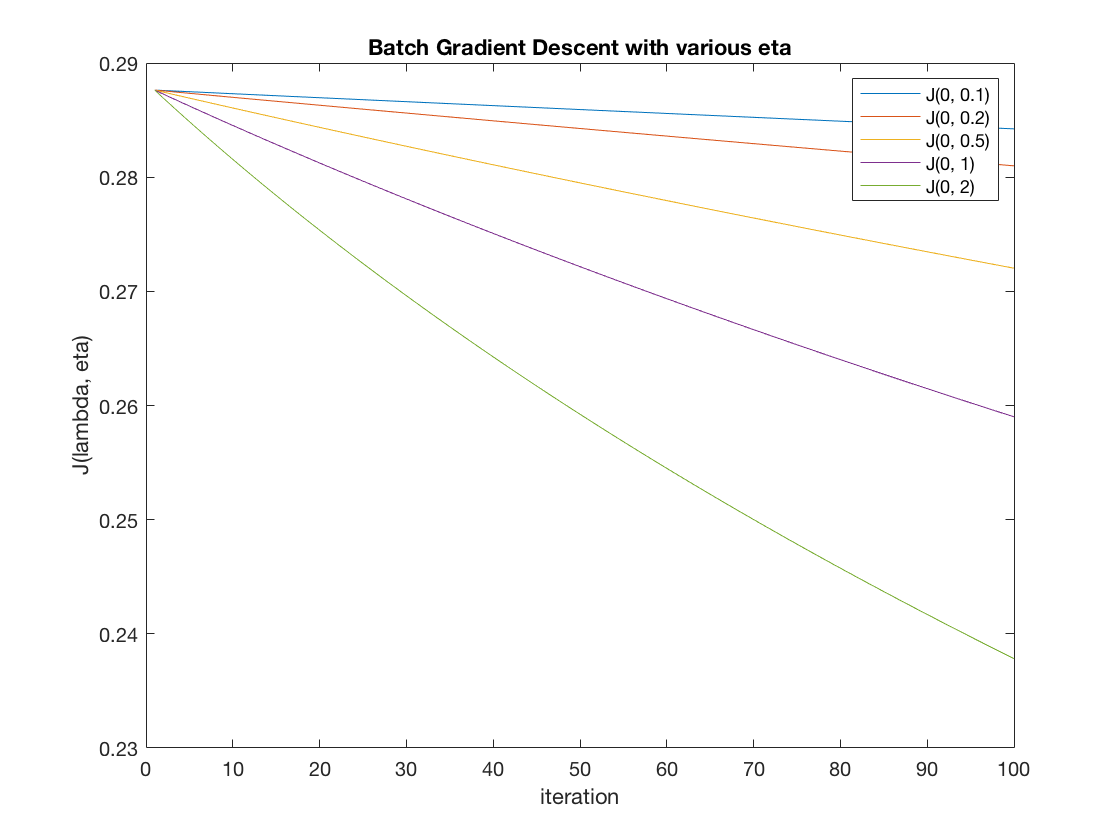

lambda = 0;
eta = [0.1 0.2 0.5 1 2 5];
Jh = cell(1, length(eta));
no_iter = cell(1, length(eta));

for l = 1 : length(eta)
    [~, Jh{l}, no_iter{l}] = neural_descent(Theta, s, X, y, eta(l), lambda, 0.000001, 100);
end

plot(1:no_iter{1}, Jh{1});hold on
for l = 2 : length(eta) - 1
    plot(1:no_iter{l}, Jh{l});
end
title('Batch Gradient Descent with various eta');
xlabel('iteration');
ylabel('J(lambda, eta)');
legend('J(0, 0.1)', 'J(0, 0.2)', 'J(0, 0.5)', 'J(0, 1)', 'J(0, 2)');
hold off

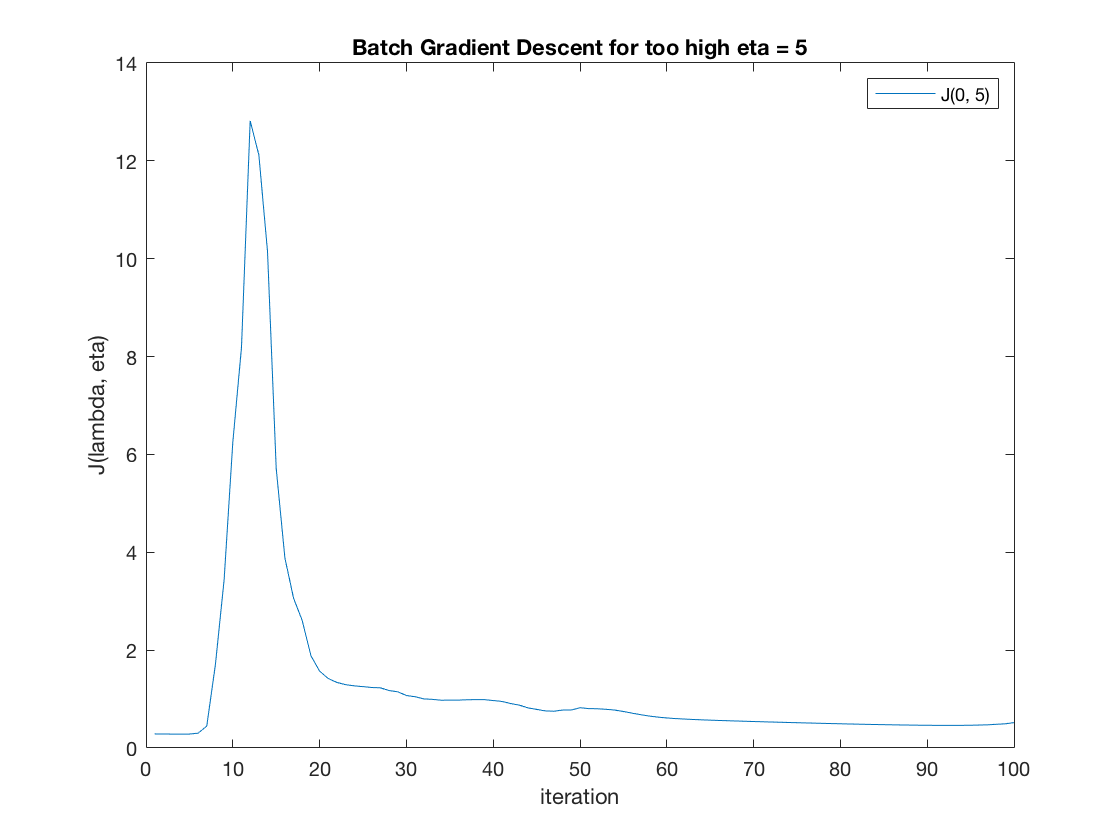

plot(1:no_iter{end}, Jh{end});
title('Batch Gradient Descent for too high eta = 5');
xlabel('iteration');
ylabel('J(lambda, eta)');
legend('J(0, 5)');